**KURAMOTO ODE**

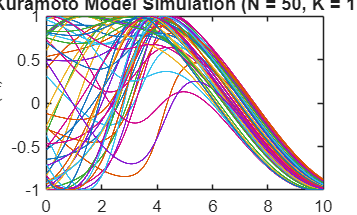

% ==========================
% (1) Set up trainig data
% ==========================
N = 50; K = 1.5; omega = rand(N, 1);	%constants 
occurences = 10000; h = 1/occurences;  
tspan = linspace(0, 10, occurences);     %set up tspan to point of synchronicity
dt = tspan(2) - tspan(1);
rng(51);
theta0 = -pi + 2*pi*rand(N, 1);

dtheta_dt = @(t, theta) omega + (K/N) * sum(sin(theta.' - theta), 2);
[t, theta_out] = ode45(dtheta_dt, tspan, theta0);

figure; plot(t, sin(theta_out), 'LineWidth', 1); 
xlabel('Time (t)'); ylabel('sin(\theta_i)'); 
title(sprintf('Kuramoto Model Simulation (N = %d, K = %.1f)', N, K)); 


% ==========================
% (2) Feature Engineering for Physics Informed Model
% ==========================
%Calculate numerical differentiation of theta:
u = sin(theta_out);
v = cos(theta_out);

dU_dt = (u(2:end, :) - u(1:end-1, :))/dt;
dV_dt = (v(2:end, :) - v(1:end-1, :))/dt; 

%Interleave u and v columns for sequential run:
Xtrain_in = zeros(occurences-1, 2*N);
Xtrain_in(:, 1:2:end) = u(1:end-1, :); % Put u in odd cols
Xtrain_in(:, 2:2:end) = v(1:end-1, :); % Put v in even cols
Xtrain_in = [Xtrain_in t(1:end-1, :)];

Ytrain_in = zeros(occurences-1, 2*N);
Ytrain_in(:, 1:2:end) = dU_dt;        % Put du/dt in odd cols
Ytrain_in(:, 2:2:end) = dV_dt;        % Put dv/dt in even cols

% ==========================
%TODO: TESTING FLATTENED INPUT VECTOR:
% ==========================
u_trimmed = u(1:end-1, :);
v_trimmed = v(1:end-1, :);
t_trimmed = repmat(t(1:end-1, :), 1, N);
Xtrain_full = [u_trimmed(:) v_trimmed(:) t_trimmed(:)];
Ytrain_full = [dU_dt(:) dV_dt(:)];

% ==========================
% (3) Regular ReLU NN
% ==========================
% numFeatures = size(Xtrain_in, 2)
% numOutputs = size(Ytrain_in, 2)
numFeatures = size(Xtrain_full, 2)

numFeatures = 3

numOutputs = size(Ytrain_full, 2)

numOutputs = 2


layers = [
    featureInputLayer(numFeatures, 'Normalization','zscore','Name','input')

    fullyConnectedLayer(256, 'Name', 'fc1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(128, 'Name', 'fc2')
    reluLayer('Name', 'relu2')
    fullyConnectedLayer(128, 'Name', 'fc3')
    reluLayer('Name', 'relu3')
    fullyConnectedLayer(numOutputs, 'Name', 'output')
]

layers =   8×1 Layer array with layers:

     1   'input'    Feature Input     3 features with 'zscore' normalization
     2   'fc1'      Fully Connected   256 fully connected layer
     3   'relu1'    ReLU              ReLU
     4   'fc2'      Fully Connected   128 fully connected layer
     5   'relu2'    ReLU              ReLU
     6   'fc3'      Fully Connected   128 fully connected layer
     7   'relu3'    ReLU              ReLU
     8   'output'   Fully Connected   2 fully connected layer

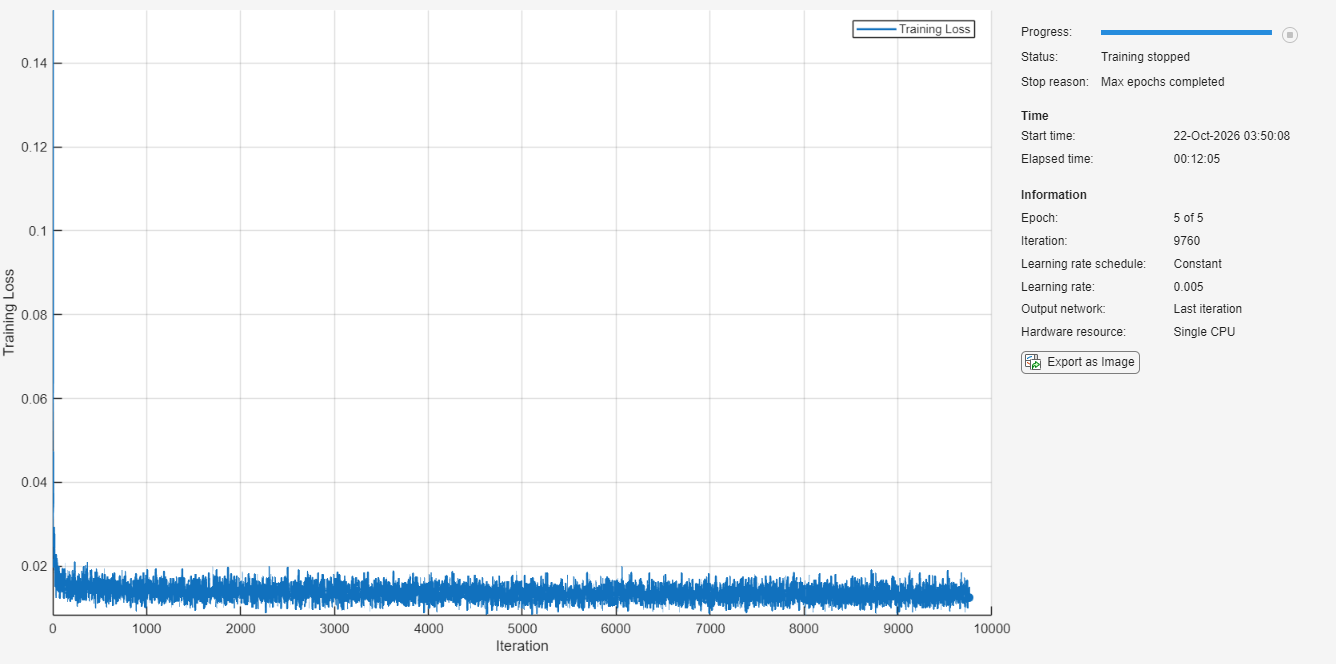


options = trainingOptions('adam', ...
    'MaxEpochs', 5, ...           
    'MiniBatchSize', 256, ...      
    'InitialLearnRate', 0.005, ...
    'Shuffle', 'every-epoch', ...
    'Verbose', false, ...
    'Plots', 'training-progress');

%trainedNet = trainnet(Xtrain_in, Ytrain_in, layers, "mse",options);
trainedNet = trainnet(Xtrain_full, Ytrain_full, layers, "mse",options);

% ==========================
% (4.1) Explicit Euler - Validation 
% ==========================
u_nn = zeros(occurences-1, N);
v_nn = zeros(occurences-1, N);
u_nn(1,:) = sin(theta0).';
v_nn(1,:) = cos(theta0).';

for i = 1:(occurences-1)
    NN_Input_I = zeros(1, 2*N);
    NN_Input_I(1, 1:2:end) = u_nn(i, :);
    NN_Input_I(1, 2:2:end) = v_nn(i, :);

    dXdt = predict(trainedNet, [NN_Input_I t(i)]);

    u_nn(i+1, :) = u_nn(i, :) + dt .* dXdt(1, 1:2:end);
    v_nn(i+1, :) = v_nn(i, :) + dt .* dXdt(1, 2:2:end);

    m = sqrt(u_nn(i+1,:).^2 + v_nn(i+1, :).^2);
    u_nn(i+1, :) = u_nn(i+1, :)./m;
    v_nn(i+1, :) = v_nn(i+1, :)./m;
end %for

Error using dlnetwork/predict (line 710)
Layer "input": Invalid input data. Invalid size of channel dimension. Layer expects input with channel dimension size 3 but received input with size 101.


fNN = unwrap(atan2(u_nn, v_nn), [], 1); 

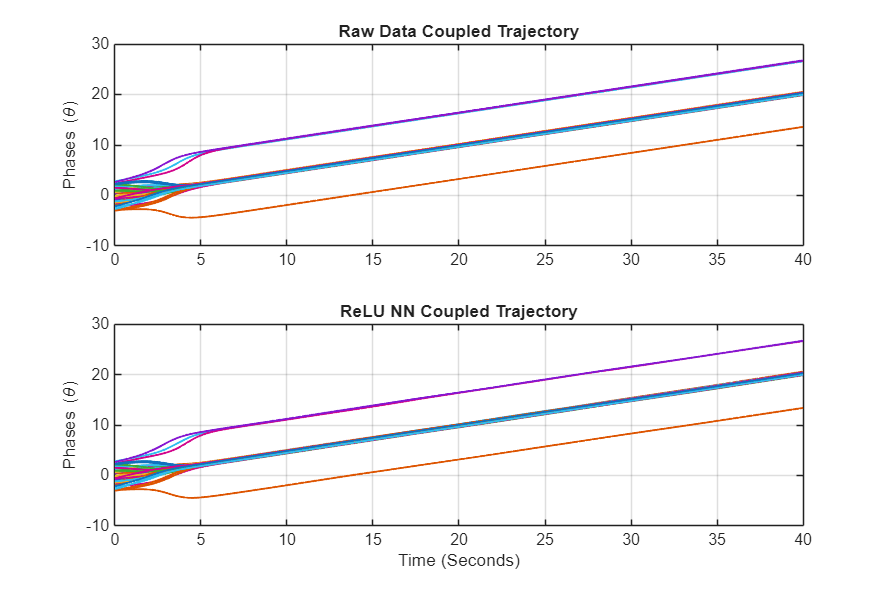

% ==========================================
% (5.1) Compare Data to NN:
% ==========================================
figure('Position', [100, 100, 900, 600]);

subplot(2, 1, 1);
plot(tspan, theta_out, 'LineWidth', 1.2);
title('Raw Data Coupled Trajectory');
ylabel('Phases (\theta)');
grid on;

subplot(2, 1, 2);
plot(tspan, fNN, 'LineWidth', 1.2);
title('ReLU NN Coupled Trajectory');
xlabel('Time (Seconds)');
ylabel('Phases (\theta)');
grid on;

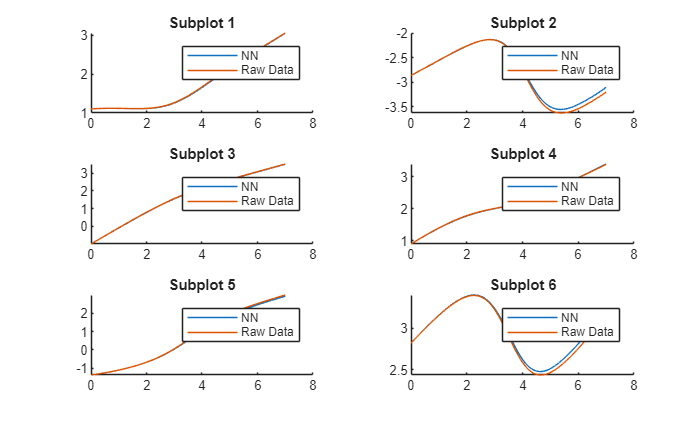

% ==========================================
% (5.2) Compare Data to NN - Individual:
% ==========================================
figure
hold on
p = tiledlayout(3,2);
ptitles = ['Subplot 1'
    'Subplot 2'
    'Subplot 3'  
    'Subplot 4'
    'Subplot 5'
    'Subplot 6'];
for i = 1:6
    nexttile;
    hold on;
    plot(tspan(1:occurences-1), fNN(1:occurences-1, i))
    plot(tspan(1:occurences-1), theta_out(1:occurences-1, i))
    legend('NN', 'Raw Data')
    title(ptitles(i, :))
    hold off;
end 
hold off

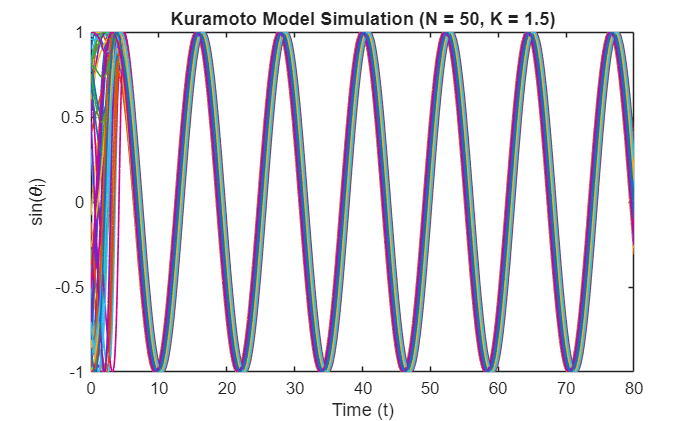

% ==========================================
% (5.3) Expanded Trajectory:
% ==========================================
occurences_new = 100000; h_new = 1/occurences_new;  
tspan_new = linspace(0, 80, occurences_new);     %set up tspan to point of synchronicity
dt_new = tspan_new(2) - tspan_new(1);
rng(52);

dtheta_dt_new = @(t, theta) omega + (K/N) * sum(sin(theta.' - theta), 2);
[t_new, theta_out_new] = ode45(dtheta_dt_new, tspan_new, theta0);

figure; plot(t_new, sin(theta_out_new), 'LineWidth', 1); 
xlabel('Time (t)'); ylabel('sin(\theta_i)'); 
title(sprintf('Kuramoto Model Simulation (N = %d, K = %.1f)', N, K)); 


u_nn_new = zeros(occurences_new-1, N);
v_nn_new = zeros(occurences_new-1, N);
u_nn_new(1,:) = sin(theta0).';
v_nn_new(1,:) = cos(theta0).';

for i = 1:(occurences_new-1)
    NN_Input_I = zeros(1, 2*N);
    NN_Input_I(1, 1:2:end) = u_nn_new(i, :);
    NN_Input_I(1, 2:2:end) = v_nn_new(i, :);

    %TODO: flatten:
    NN

    dXdt = predict(trainedNet, [NN_Input_I t_new(i)]);

    u_nn_new(i+1, :) = u_nn_new(i, :) + dt_new .* dXdt(1, 1:2:end);
    v_nn_new(i+1, :) = v_nn_new(i, :) + dt_new .* dXdt(1, 2:2:end);

    m = sqrt(u_nn_new(i+1,:).^2 + v_nn_new(i+1, :).^2);
    u_nn_new(i+1, :) = u_nn_new(i+1, :)./m;
    v_nn_new(i+1, :) = v_nn_new(i+1, :)./m;
end %for

fNN_new = unwrap(atan2(u_nn_new, v_nn_new), [], 1); 

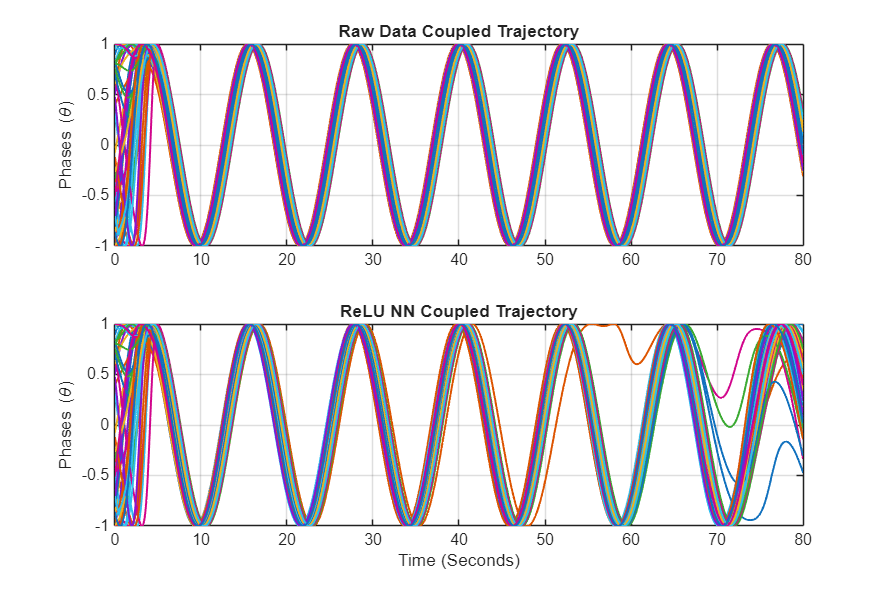

% ==========================================
% (5.4) Compare Data to NN:
% ==========================================
figure('Position', [100, 100, 900, 600]);

subplot(2, 1, 1);
plot(tspan_new, sin(theta_out_new), 'LineWidth', 1.2);
title('Raw Data Coupled Trajectory');
ylabel('Phases (\theta)');
grid on;

subplot(2, 1, 2);
plot(tspan_new, sin(fNN_new), 'LineWidth', 1.2);
title('ReLU NN Coupled Trajectory');
xlabel('Time (Seconds)');
ylabel('Phases (\theta)');
grid on;

%%%%%%STORE NN COEFFICIENTS DATA
filename = "FitRNet_Storage_THETA.xlsx";
numLayers = size(trainedNet.Layers, 1) / 2;

for j = 1:numLayers
    if j == 1
        A = trainedNet.Layers(j*2).Weights ./ trainedNet.Layers(1).StandardDeviation;
        writematrix(A, filename,'Sheet', j, 'Range', 'A1')
    else 
        writematrix(trainedNet.Layers(j*2).Weights, filename,'Sheet', j, 'Range', 'A1')
    end %if 
end %for 

filename = "FitRNet_Storage_CCOEFF.xlsx";
for j = 1:numLayers
    if j == 1
        A = trainedNet.Layers(j*2).Bias - (trainedNet.Layers(j*2).Weights * (trainedNet.Layers(1).Mean ./ trainedNet.Layers(1).StandardDeviation)');
        writematrix(A, filename,'Sheet', j, 'Range', 'A1')
    else
        writematrix(trainedNet.Layers(j*2).Bias, filename,'Sheet', j, 'Range', 'A1')
    end %if 
end %for 

%%%%%%STORE RAW DATA
filename = "FitRNet_Storage_RawData.xlsx";
writematrix(theta_out, filename,'Sheet', 1, 'Range', 'A1')
writematrix(t, filename,'Sheet', 2, 'Range', 'A1')

%%%%%%STORE OMEGA PARAMETER DATA
csvFile_rawdata = "FitRNet_Storage_OMEGA.csv";
writematrix(omega, csvFile_rawdata);
